In this example, we consider the control stabilization of a fluttered pipe conveying fluid as shown below.

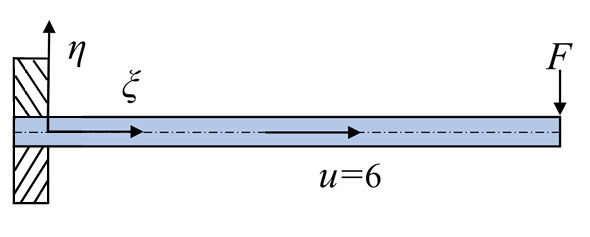

In this demo, we set the flow velocity to be 6, where the pipe system is under flutter. We construct a 2D unstable SSM around the unstable straight configuration. We expect there exists a stable limit cycle on the SSM. Under the addition of external control input at the free end, we are concerned with the post-flutter dynamics. 

We refer to "*M. Li, H. Yan, L. Wang: Nonlinear model reduction for a cantilevered pipe conveying fluid: A system with asymmetric damping and stiffness matrices. MSSP. 2023. *[*https://doi.org/10.1016/j.ymssp.2022.109993*](https://doi.org/10.1016/j.ymssp.2022.109993)" for more details on the ODEs. 

clearvars
close all; clc

## Model Setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \epsilon(\mathbf{f}^{ext}(\Omega t)+\mathbf{u}(t))$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) +\epsilon\mathbf{F}^{ext}$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

% system parameters
nmodes = 4;
fcload = 1;
flowspeed = 6;
miu = 0;
Gamma=0;
alpha=0.001;
beta=0.2;
[M, C, K, fnl, fext] = build_model(nmodes,flowspeed,beta,miu,Gamma,alpha,'clamped-free','nonlinear_damp');

Getting linear and nonlinearity coefficients
Loaded coefficients from storage


n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)

**Create dynamical system **

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',10,'Nmax',10,'notation','multiindex')
set(DS.Options,'RayleighDamping',false)
epsilon  = 1e-3;
set(DS,'epsilon',epsilon);

## Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();


 The first 8 nonzero eigenvalues are given as 
   1.0e+02 *
   0.0076 + 0.1353i
   0.0076 - 0.1353i
  -0.0704 + 0.4747i
  -0.0704 - 0.4747i
  -0.1225 + 0.0190i
  -0.1225 - 0.0190i
  -0.1240 + 1.0973i
  -0.1240 - 1.0973i


## SSM Reduced dynamics - autonomous part

We take the pair of unstable modes as the master subspace and compute the corresponding 2D unstable SSM

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
order = 9;
resonant_modes = [1,2]; 
S.choose_E(resonant_modes);

sigma_out = -16
sigma_in = -16


[W0,R0] = S.compute_whisker(order);

Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 2.77E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 3.14E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.44E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.12E-02 MB
Manifold computation time at order 6 = 00:00:00
Estimated memory usage at order  6 = 4.69E-02 MB
Manifold computation time at order 7 = 00:00:00
Estimated memory usage at order  7 = 5.77E-02 MB
Manifold computation time at order 8 = 00:00:00
Estimated memory usage at order  8 = 6.72E-02 MB
Manifold computation time at order 9 = 00:00:00
Estimated memory usage at order  9 = 8.30E-02 MB


auData = construct_autoData(DS, resonant_modes, R0);
%% Reduced dynamics in symbolic form
lamdMaster = DS.spectrum.Lambda(resonant_modes);
options = struct();
options.isauto = true; 
options.isdamped = true;
options.numDigits = 4;
y = reduced_dynamics_symbolic(lamdMaster,R0,options)

$$y = \left(\begin{array}{c} 0.009578\,{\rho_{1}}^{9}+0.00558\,{\rho_{1}}^{7}-0.05442\,{\rho_{1}}^{5}-1.006\,{\rho_{1}}^{3}+0.7631\,\rho_{1}\\ 0.009245\,{\rho_{1}}^{8}+0.047\,{\rho_{1}}^{6}+0.1781\,{\rho_{1}}^{4}+0.5574\,{\rho_{1}}^{2}+13.53 \end{array}\right)$$

we indeed see a converged root, which indicates that the system has isola under the addition of forcing. In addition, cubic approximation presents analytical prediction of the critical value of forcing amplitude for the merging of main and isola branches.

lamda  = zeros(n,1);
lamda(1)=1.8751040687119611664453082410782141625701117335311;
lamda(2)=4.6940911329741745764363917780198120493898967375458;
lamda(3)=7.8547574382376125648610085827645704578485419292300;
lamda(4)=10.995540734875466990667349107854702939612972774652;
lamda(5)=14.137168391046470580917046812551772068603076792975;
lamda(6)=17.278759532088236333543928414375822085934519635550;
lamda(7)=20.420352251041250994415811947947837046137288894544;
lamda(8)=23.561944901806443501520253240198075517031265990051;
m = 100;
x_shapes = linspace(0,1,m);
phi_x  = cell(n,1);
for j = 1:m
    x    = x_shapes(j);
    for k=1:n
       % x    = 1;
       phin = cos(lamda(k)*x)-cosh(lamda(k)*x)-(cos(lamda(k))+cosh(lamda(k)))/(sin(lamda(k))+sinh(lamda(k)))*...
            (sin(lamda(k)*x)-sinh(lamda(k)*x));%clamped-free
       phi_x{j}(k) = phin;
       % phiend(k) = phin;
    end
end
phiend = phi_x{end}';

Bext     = phiend;
set(DS,'D',Bext);

###  Construct initial condition

tf     = 12; % <=8 is fine
nsteps = 333;
z0     = 0.0*V(:,1); % initial condition (here we select it based on the modal shapes)
z0(1)  = 0.001;
outdof = 1:2*n;
set(DS.Options, 'outDOF', outdof);
set(DS,'u',[]);
traj = transient_traj_on_auto_ssm(DS, resonant_modes, W0, R0, tf, nsteps, outdof, z0);
[tInt,zInt] = time_integration_transient(DS,2*pi/tf,...
    'nSteps', nsteps, 'nCycles', 1, ...
    'integrationMethod','ode45','outdof',outdof,'init',z0);

% we take the state at t=10 as the initial time to apply control
[~,idx] = min(abs(tInt-10));
z02     = zInt(idx,:)';

## Linear model order reduction analysis

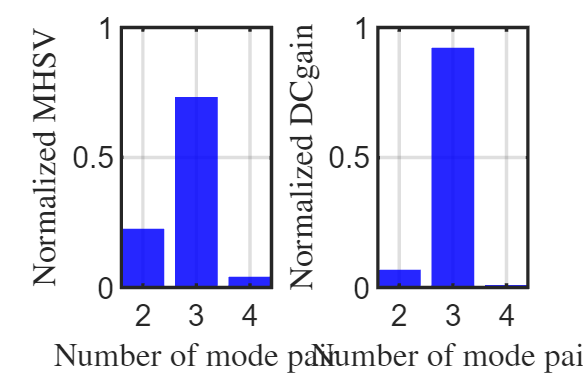

res = Linear_MOR(DS,4,phiend);

## **Free Vibration**

tf      = 1.5;
om = 2*pi/tf;
set(DS,'u',[]);
[tfullwo, xfullwo] = time_integration_transient(DS,om,'nCycles',...
    1, 'nSteps', nsteps,...
    'integrationMethod','ode45','outdof',outdof,'init',z02);

## Closed loop control with 3 receding horizons

% control parameters
cont   = struct();
cont.Q    = 1e4*eye(2*n)*(phiend'*phiend);
cont.Rhat = 0.001*(phiend'*phiend);
cont.Mhat = 1e4*eye(2*n)*(phiend'*phiend); % 1e4

ts = [0 0.4 1 tf];
nint = numel(ts)-1;
xf = z02;
trajs = cell(nint,1); tfullc = cell(nint,1); xfullc = cell(nint,1);
for k=1:nint
    ta = ts(k); tb = ts(k+1);
    tspan = linspace(ta,tb,nsteps);
    traj   = LQR_closed_loop(DS,xf,'linear',tspan,auData,W0,resonant_modes,[1,2,5,6],cont);
    ufun  = @(t) transpose(interp1(traj.time,traj.ut',t));
    set(DS,'u',ufun);
    [tk, xk,xkf] = time_integration_transient(DS,2*pi/(tb-ta),'nCycles',...
        1, 'nSteps', nsteps,...
        'integrationMethod','ode15s','outdof',outdof,'init',xf,'ts',ta);
    % update initial condition
    xf = xkf';
    % record results
    trajs{k}  = traj;
    tfullc{k} = tk;
    xfullc{k} = xk;
end

pl
  -0.8455 - 0.0813i
  -0.8455 + 0.0813i
p0
  -0.8455 - 0.0813i
  -0.8455 + 0.0813i
Time for backward simulation of Riccati ODE is 5.274050e-02
Time for backward simulation of compensated ODE is 1.448052e-01
历时 0.185128 秒。
Time for forward simulation of ODEs for modal coordinates is 1.865054e-01
pl
  -0.1650 + 0.3473i
  -0.1650 - 0.3473i
p0
  -0.1650 + 0.3473i
  -0.1650 - 0.3473i
Time for backward simulation of Riccati ODE is 9.594700e-03
Time for backward simulation of compensated ODE is 1.482165e-01
历时 0.170933 秒。
Time for forward simulation of ODEs for modal coordinates is 1.729319e-01
pl
  -0.0712 - 0.0228i
  -0.0712 + 0.0228i
p0
  -0.0712 - 0.0228i
  -0.0712 + 0.0228i
Time for backward simulation of Riccati ODE is 9.901800e-03
Time for backward simulation of compensated ODE is 1.298982e-01
历时 0.139943 秒。
Time for forward simulation of ODEs for modal coordinates is 1.409663e-01


## Plot

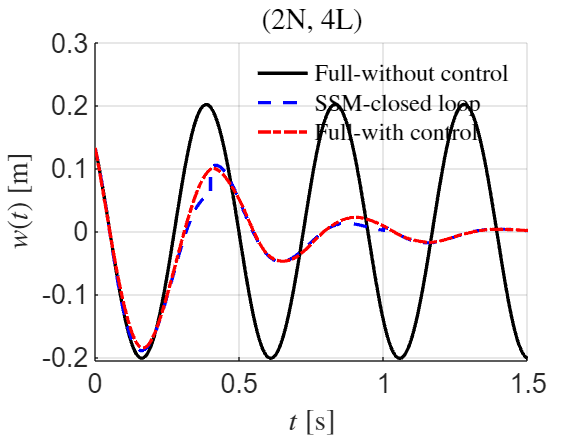

figure; hold on
plot(tfullwo, xfullwo(:,1:4)*phiend,'k-','DisplayName','Full-without control','LineWidth',2);
plot([trajs{1}.time, trajs{2}.time, trajs{3}.time], [phiend'*trajs{1}.zt(1:4,:), phiend'*trajs{2}.zt(1:4,:), phiend'*trajs{3}.zt(1:4,:)],'b--','DisplayName','SSM-closed loop','LineWidth',2);
plot([tfullc{1}; tfullc{2}; tfullc{3}], [xfullc{1}(:,1:4)*phiend; xfullc{2}(:,1:4)*phiend; xfullc{3}(:,1:4)*phiend],'r-.','DisplayName','Full-with control','LineWidth',2);
xlabel('$t$ [s]','Interpreter',"latex")
zk = strcat('$w(t)$ [m]');
ylabel(zk,'Interpreter','latex');
legend('show','Interpreter','latex',Location='northeast')
legend boxoff
title('(2N, 4L)','Interpreter','latex')
set(gca,'FontSize',16);
grid on
ylim([-0.205, 0.3])

## Control inputs

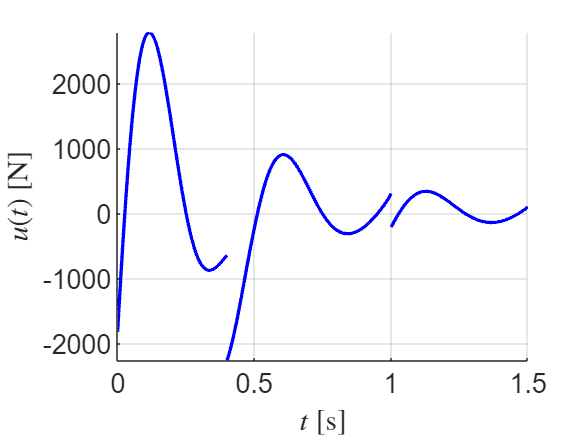

figure; hold on
for k=1:nint
    plot(trajs{k}.time, trajs{k}.ut(1,:),'b-','LineWidth',2);
end
xlabel('$t$ [s]','Interpreter',"latex")
ylabel('$u(t)$ [N]','Interpreter','latex');
set(gca,'FontSize',16);
grid on, axis tight